# Tercer Examen Parcial

# Primavera 2023

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 3 antes de las 11:25 horas. 

**Aseguráte que tus resultados se despliegan en el archivo que subas.**

Al final del script debes incluir las funciones usadas para resolver las preguntas.

Cada pregunta vale 5 puntos.

Si no usas la función indicada se restan 2 puntos en la respuesta. Si no usas el método indicado la respuesta no cuenta.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

**Recuerda salvar frecuentemente tu archivo.**

Puede ser conveniente limpiar periódicamente el espacio de trabajo (comando clear).

En el caso extremo de gráficas que aparecen mal, puedes salir y volver a entrar a la sesión.

## 1. Ecuación diferencial ordinaria de primer orden - Método de paso variable

Hasta ahora, hemos supuesto que el intervalo t0 a tf está dado como parte de la especificación del problema. Sin embargo,en muchas situaciones, determinar el valor de tf es un aspecto importante del problema.

Si se drena el agua desde un tanque cilindrico vertical abriendo una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$y^{\prime } =-k\sqrt{y}$           (*y* en metros y *t* en minutos)

donde *k* es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero.

¿En cuántos minutos se vaciará un tanque que inicialmente tiene 3 metros de agua? (k = 0.06)

Usa el código de tu función ode23 en el script. Para el while cuando $y\le \textrm{eps}$.

Grafica y(t).

MaxStep = 1000;
rtol = 1e-3;
h = 0.0001;
y0 = 3;
t0 = 0;

a) Define la función f     (y'=f(t,y)

k = 0.06;
f = @(t,y) -k*sqrt(y)

f = function_handle with value:
    @(t,y)-k*sqrt(y)


b) Ejecuta el ciclo de ode23. Para el while cuando $y\le \textrm{eps}$

    pow = 1/3;
    t = t0;
    y = y0;
    condicion = true;
    i = 1;
    vecT = t;
    vecY = y;
    while condicion
        s1 = f(t,y);
        s2 = f(t+h/2, y+h*s1/2);
        s3 = f(t+3*h/4, y+h*3*s2/4);
        tNext = t + h;
        yNext = y + h*(2*s1 + 3*s2 + 4*s3)/9;
        s4 = f(tNext, yNext);
        e = h*(-5*s1 + 6*s2 + 8*s3 - 9*s4)/72;
        err = norm(e/yNext, inf);
        if err<rtol
            vecT = [vecT, tNext];
            vecY = [vecY, yNext];
            t = tNext;
            y = yNext;
            i = i+1;
        end
        s = (rtol/err)^pow;
        h = s*h;
        if 1.1*abs(h)>= abs(MaxStep-t(end))
            h = MaxStep-t(end);
        end
        condicion = y>eps && i<MaxStep;
    end
    t = vecT';
    y = vecY';
t1 = t;
y1 = y;

c) Despliega en cuántos minutos se vacia el tanque 

Tiempo = t1(i)

Tiempo = 57.6736

d) Grafica y.

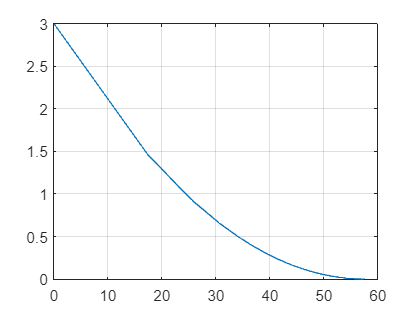

plot(t1,y1)
grid on

## 2. Ecuación diferencial ordinaria lineal de tercer orden - Método de múltiples pasos

Resuelve la siguiente ecuación.

y′′′(t) + 4y′′(t) + 5y′(t) + 2y(t) = 2t^2 + 10t + 8

y(0) = 1, y′(0) = −1, y′′(0) = 3.

a) Plantea la función f

t0 = 0;
tf = 10;
h = 1;
y0 = [1;-1;3];
M = [0 1 0; 0 0 1; -2 -5 -4];
b = @(t) [0;0;2*t.^2+10*t+8];
f = @(t,yzx)  M*yzx + b(t);

b) Usa el método RK4

tic
[t2,y2] = RK4(f,t0,y0,h,tf);
toc

Elapsed time is 0.010677 seconds.


c) Usa el método ABM4o, igual al ABM4 pero que solo guarda los últimos cuatro valores de la función

tic
[t3,y3] = AMB4o(f,y0,t0,tf,h);
toc

Elapsed time is 0.008763 seconds.


d) Grafica las soluciones y(t)

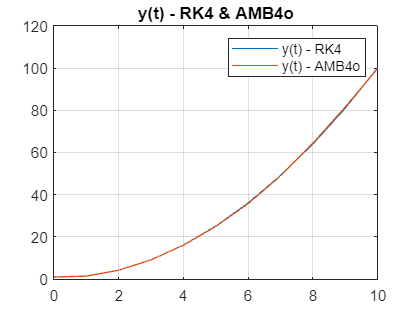

plot(t2,y2(1,:))
hold on
plot(t3,y3(1,:))
title("y(t) - RK4 & AMB4o")
legend("y(t) - RK4", "y(t) - AMB4o")
grid on
hold off

e) ¿Cuál método es más rápido? 

El AMB4o es más rápido pues optimiza el factor fv  al no tener que almacenar tantos valores.

Es más eficiente predecir un valor y luego corroborar el error que simplemente ir calculando una phi con tantos factores. 

## 3. Integración numérica

Numerical evaluation of the integral $Q = \int_a^b f(x)\, \mathrm{d}x$ typically begins with dividing the interval $(a, b)$ into $n$ uniformly or nonuniformly spaced subintervals defined by the points  $(x_i, \,x_{i+1}),\; i=1,\ldots, n+1.$ The integral over these smaller subintervals $Q_i = \int_{x_i}^{x_{i+1}} f(x)\, \mathrm{d} x$ is then approximated by evaluating $f$ at a small number of *uniformly* or *nonuniformly* spaced node points within the subinterval, fitting a polynomial to these points, and then integrating the polynomial to produce a quadrature rule.

Summing $Q_i$ over all subintervals yields the numerical approximation of the integral $Q$. A popular quadrature method of this form is [*Simpson's 3/8 rule*](https://en.wikipedia.org/wiki/Simpson%27s_rule). Here, four uniformly spaced node points are used; the endpoints and two points of the subinterval. The quadrature rule is: 

                                                                     
$$Q_i  = H_i  \frac{f( x_{i} ) + 3f( x_{i+1/3} )  +  3f( x_{i+2/3} )  + f( x_{i+1})}{ 8
}$$


Where: $H_i = x_{i+1} - x_i$

Write a script that implements Simpson's 3/8 rule using uniformly spaced subintervals **without using a loop**. Your script should use 4 inputs:

- `fun` = a handle to the integrand function

- `a` = lower limit of integration

- `b` = upper limit of integration

- `n` = number of uniform subintervals

and display 1 output:

- `Q` = value of the integral

Test your solution on the function $f(x)=1 - x + x^3$ over the interval $[0,1]$. The result should be 0.75.

**Hint**: Before implementing your solution, it may be helpful to write out the first several terms of the summation formula. 

- What pattern do you observe? 

- How can you obtain the corresponding sum from a vector of node locations and the corresponding vector of function values?

a = 0;                          % lower limit of integration
b = 1;                          % upper limit of integration
n = 10;                         % number of uniform subintervals [xi, xi+i]
fun = @(x) 1 - x + x.^3;
h = (b-a)/(n*3);
x = a:h:b;
Q = h*3/8*sum((fun(x(1:3:end-3)) + 3*fun(x(2:3:end-2)) + 3*fun(x(3:3:end-1)) + fun(x((4:3:end)))))

Q = 0.7500

## 4. Stiff

Resuelve la siguiente ecuación en [0,4]

$\frac{\mathrm{d}}{\mathrm{d}t}y=\lambda y+\frac{1}{1+t^2 }-\lambda \tan^{-1} \left(t\right)$; $y\left(0\right)=0$.

Usa el método de Euler y el método de Euler hacia atrás.  

Considera λ = −1,−10,−50, y h = 0.5, 0.1, 0.001. 

Comenta los resultados.

to = 0;
tf = 4;
yo = 0;

Euler con λ = −1 y h = 0.5. Grafica la solución y(t) agregando un título con los parámetros usados.

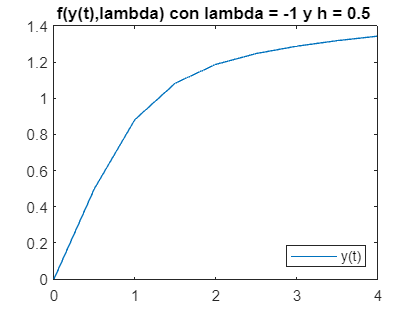

l = -1;
h = 0.5;
f = @(t,y) l*y+1/(1+t^2)-l*atan(t);
[t4,y4] = odeEuler(f, to, yo, h, tf);
plot(t4,y4);title("f(y(t),lambda) con lambda = -1 y h = 0.5 ");legend("y(t)","Location","southeast")

a) Euler con λ = −10 y h = 0.5. Gr-afica la solución y(t).

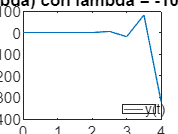

l = -10;
h = 0.5;
f = @(t,y) l*y+1/(1+t^2)-l*atan(t);
[t5,y5] = odeEuler(f, to, yo, h, tf);
plot(t5,y5);title("f(y(t),lambda) con lambda = -10 y h = 0.5 ");legend("y(t)","Location","southeast")

b) Euler con λ = −10 y h = 0.1. Grafica la solución y(t).

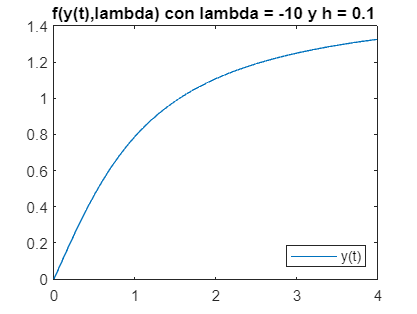

l = -10;
h = 0.1;
f = @(t,y) l*y+1/(1+t^2)-l*atan(t);
[t6,y6] = odeEuler(f, to, yo, h, tf);
plot(t6,y6);title("f(y(t),lambda) con lambda = -10 y h = 0.1 ");legend("y(t)","Location","southeast")

c) Euler con λ = −50 y h = 0.1. Grafica la solución y(t).

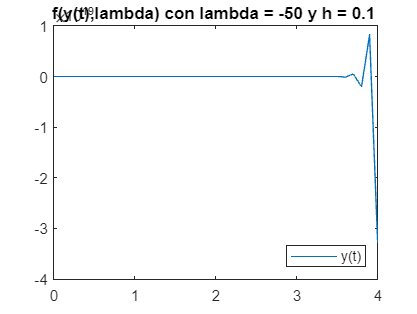

l = -50;
h = 0.1;
f = @(t,y) l*y+1/(1+t^2)-l*atan(t);
[t7,y7] = odeEuler(f, to, yo, h, tf);
plot(t7,y7);title("f(y(t),lambda) con lambda = -50 y h = 0.1 ");legend("y(t)","Location","southeast")

d) Euler con λ = −50 y h = 0.001. Grafica la solución y(t).

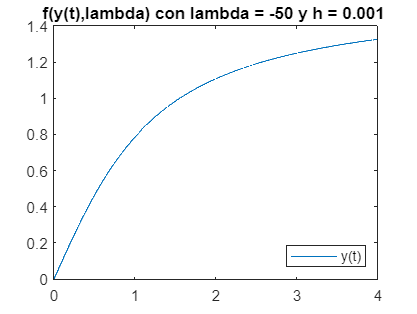

l = -50;
h = 0.001;
f = @(t,y) l*y+1/(1+t^2)-l*atan(t);
[t8,y8] = odeEuler(f, to, yo, h, tf);
plot(t8,y8);title("f(y(t),lambda) con lambda = -50 y h = 0.001 ");legend("y(t)","Location","southeast")

e) Backward Euler con λ = −50 y h = 0.5. Grafica la solución y(t).

HINT: la ecuación implícita para $y_{i+1}$ puede resolverse explícitamente.

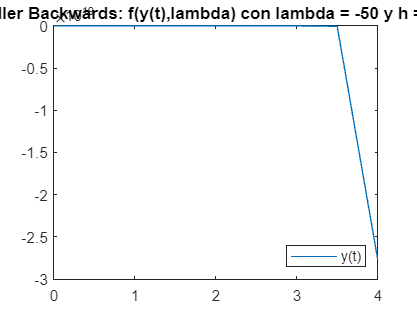

l = -50;
h = 0.5;
[t9,y9] =backEuler(f, to,yo,tf,h);
plot(t9,y9);title("Euller Backwards: f(y(t),lambda) con lambda = -50 y h = 0.5 ");legend("y(t)","Location","southeast")

Comentarios

La función f(t, y(t), lambda) tiene variaciones muy repentinas en el parámetros lambda pues existe una exponencial y una función tangente que dependen de lambda. De tal forma, cuando lambda crece mucho, la función tiene cambios extremadamente drásticos. Al hacer el cálculo de la solución del sistema, tenemos que elegir un paso que pueda capturar con presición estas variaciones. Podemos notar en la primera gráfica con una lambda de -1 y una h de .5, la función se grafica adecuadamente. En la segunda gráfica cuando aumentamos la lambda a -10, la h de 0.5 no es suficientemente pequeña y la gráfica pierde toda presición. En la tarcera gráfica bajamos la h a 0.1 y una vez más tenemos una buena gráfica. Podemos observar este patrón a lo largo de las gráficas. Si utilizamos una lambda muy grande, nececitamos una h igualmente pequeña. 

### Inserta aquí las funciones usadas

#### RK4

function [t,y] = RK4(f,t0,y0,h,tf)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:(n-1)
        k1=f(t(i),y(:,i));
        k2=f(t(i)+(1/2)*h,y(:,i)+(1/2)*k1*h);
        k3=f(t(i)+(1/2)*h,y(:,i)+(1/2)*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end

#### ABM4o

function [t,y]=AMB4o(f,y0,t0,tf,h)
    steps=4; 
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0) ,n);
    fv=zeros(length(y0),steps);
    [t(1:steps),y(:,1:steps)]=RK4(f,t0,y0,h,t0+h*(steps-1));
    fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps)); %agarra un valor de la t, y la primer columna del y y aplica la funcion f.
    for i=4:n-1
        %predictor-Adams-Bashford
        y(:,i+1)= y(:,i) + (h/24)*( 55*fv(:,steps) - 59*fv(:,steps-1) + 37*fv(:,steps-2) - 9*fv(:,steps-3));
        fv(:,1:steps-1) = fv(:,2:steps);
        fv(:,steps)=f(t(i+1),y(:,i+1));
        %corrector
        y(:,i+1)=y(:,i) + (h/24)*( 9*fv(:,steps) + 19*fv(:,steps-1) - 5*fv(:,steps-2) + fv(:,steps-3));
        fv(:,steps)=f(t(i+1),y(:,i+1));
        
    end
end

#### Euler Normal

function [t,y] = odeEuler(f, to, yo, h, tf)
    t = to:h:tf;
    n = length(t);
    m = length(yo);
    y = zeros(m,n);
    y(:,1) = yo;
    for i=1:n-1
        y(:,i+1) = y(:,i) + f(t(i),y(:,i))*h;
    end
end

**Euller Backwards**

function [t,y] = backEuler(f,t0,y0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m = length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i = 1:n-1
        ynew = y(:,i)+h*(f(t(i),y(:,i)));
        y(:,i+1) = y(:,i)+h*f(t(i+1),ynew);
   end
end